waypoints = [0 0; 0 10; 10 10; 5 10; 11 9; 4 -5];
% Define the total time and the sample rate
sampleTime = 0.05;               % Sample time [s]
tVec = 0:sampleTime:50;          % Time array
initPose = [waypoints(1,:)'; 0]; % Initial pose (x y theta)
bicycle = bicycleKinematics("VehicleInputs","VehicleSpeedHeadingRate","MaxSteeringAngle",pi/8);
% carLike =ackermannKinematics("WheelBase",1.762);
% v=1;
% psiDot=30;
% derivative(carLike,initPose,[v psiDot])
controller1 = controllerPurePursuit("Waypoints",waypoints,"DesiredLinearVelocity",1,"MaxAngularVelocity",3*pi,'LookaheadDistance',2);
% [vel,angvel,lookaheadpoint]=controller1(initPose(1:3,:))



goalPoints = waypoints(end,:)';
goalRadius = 1;
initpose1=[0,0,0];

[tBicycle,bicyclePose] = ode45(@(t,y)derivative(bicycle,y,HelperRobot(controller1,y,goalPoints,goalRadius)),tVec,initPose);

bicycleTranslations = [bicyclePose(:,1:2) zeros(length(bicyclePose),1)];
bicycleRot = axang2quat([repmat([0 0 1],length(bicyclePose),1) bicyclePose(:,3)])

bicycleRot =     1.0000         0         0         0
    0.9999         0         0    0.0104
    0.9998         0         0    0.0207
    0.9995         0         0    0.0311
    0.9991         0         0    0.0414
    0.9987         0         0    0.0518
    0.9981         0         0    0.0621
    0.9974         0         0    0.0724
    0.9966         0         0    0.0827
    0.9957         0         0    0.0931


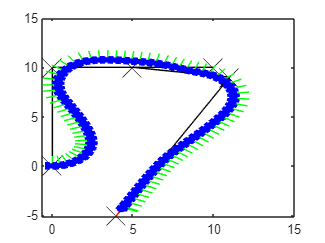


figure
plot(waypoints(:,1),waypoints(:,2),"kx-","MarkerSize",20);
hold all
plotTransforms(bicycleTranslations(1:10:end,:),bicycleRot(1:10:end,:),'MeshFilePath','groundvehicle.stl',"MeshColor","b");
view(0,90)